cs_vals = randi([0 1], 12, 10);

victim_cs_vals = randi([0 1], 12, 10);

[victim_cs_ind_y, victim_cs_ind_x] = find(victim_cs_vals == 1);

jammer_cs_vals = randi([0 1], 12, 10);

[jammer_cs_ind_y, jammer_cs_ind_x] = find(jammer_cs_vals == 1);

figure;
imagesc(cs_vals);
cmap = colormap('gray');
grid();
hold on;
scatter(jammer_cs_ind_x, jammer_cs_ind_y, 5000, 'g.');
scatter(victim_cs_ind_x, victim_cs_ind_y, 500, 'rx', 'LineWidth', 2);

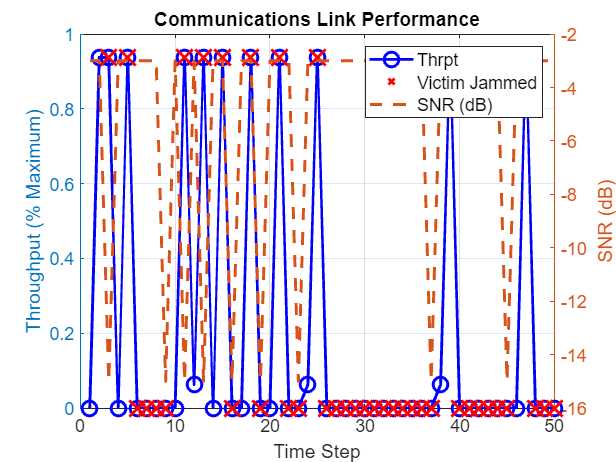

good_or_bad_channel = zeros(1, numTrials);
    for i = 1:numTrials
        if cs_matrix(victim_cs_vals(i), i) == 1
            good_or_bad_channel(i) = 1;
        end
    end

    SNR_vals = good_or_bad_channel * (Parameters.goodSNRdB - Parameters.badSNRdB) + ...
        Parameters.badSNRdB;
    
    figure;
    yyaxis left;
    plot(Throughput_results, 'b-o', 'MarkerSize', 10, 'LineWidth', 2);
    ylabel("Throughput (% Maximum)");
    hold on;
    scatter(find(victim_cs_vals == jammer_cs_vals), ...
        Throughput_results(find(victim_cs_vals == jammer_cs_vals)), 250, 'rx', 'LineWidth', 2);
    yyaxis right;
    plot(SNR_vals, '--', 'LineWidth', 2);
    grid();
    xlabel("Time Step", 'FontSize', 12);
    ylabel("SNR (dB)", 'FontSize', 12);
    legend(["Thrpt", "Victim Jammed", "SNR (dB)"], 'FontSize', 12);
    set(gca,'fontsize', 12);
    title("Communications Link Performance");